a = readstruct('../data/avsleftcam-result/poses.xml');

% Load data
tvec = zeros(numel(a.data), 3);
rvec = zeros(numel(a.data), 3);
rmat = cell(numel(a.data),1);
for i=1:numel(a.data)
    rvec_str = split(a.data(i).rvec, ' ');
    rvec_str = rvec_str(rvec_str ~= "");

    rvec(i,:) = [str2double(rvec_str(1)),...
        str2double(rvec_str(2)),...
        str2double(rvec_str(3))];

    tvec_str = split(a.data(i).tvec, ' ');
    tvec_str = tvec_str(tvec_str ~= "");
    tvec(i,:) = [str2double(tvec_str(1)),...
        str2double(tvec_str(2)),...
        str2double(tvec_str(3))];
end

% Convert from rotation vector to rotation matrix
for i=1:numel(a.data)
    rotmat = rotvec2mat3d(rvec(i,:));
    rmat{i} = rotmat;
end


## Draw camera position & orientation

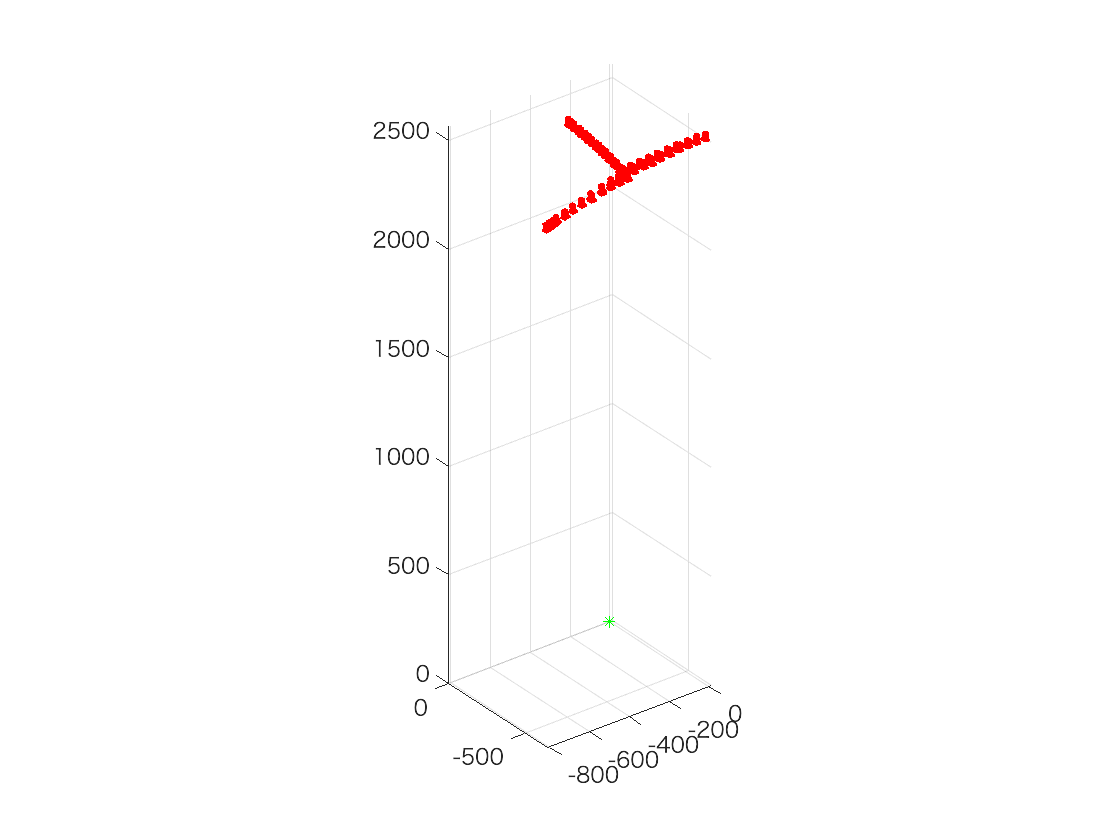

% rvec, tvec: ボード座標系からカメラ座標系への変換

figure;
plot3(0,0,0,"g*"); hold on;
for i=1:numel(a.data)
cam = plotCamera(AbsolutePose=rigidtform3d(rmat{i}, tvec(i,:)), Size=10);
hold on;
end
grid on;
axis equal;
axis manual;